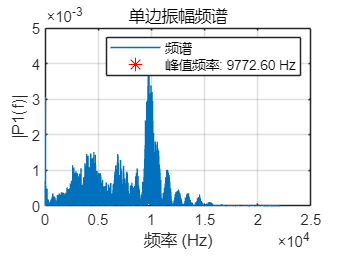

% 1. 读取音频文件
[file, fs] = audioread('sample_track.wav');

% 2. 预处理音频信号（截取前 5 秒）
duration = 10; % 秒
N = duration * fs;
if length(file) < N
    N = length(file);
end
signal = file(1:N);

% 3. 执行 FFT
Y = fft(signal);
P2 = abs(Y / N);
P1 = P2(1:N/2+1);
P1(2:end-1) = 2 * P1(2:end-1);

% 4. 计算频率轴
f = fs * (0:(N/2)) / N;

% 5. 绘制频谱图
figure;
plot(f, P1)
title('单边振幅频谱')
xlabel('频率 (Hz)')
ylabel('|P1(f)|')
grid on

% 6. 标出峰值频率（可选）
[peak, index] = max(P1);
peak_freq = f(index);
hold on
plot(peak_freq, peak, 'r*', 'MarkerSize', 10)
legend('频谱', sprintf('峰值频率: %.2f Hz', peak_freq))
hold off